clc;clear;close all;
vid = videoinput('winvideo','1','MJPG_1024x576');
preview(vid);

disp('按任一鍵開始拍照取像')

按任一鍵開始拍照取像


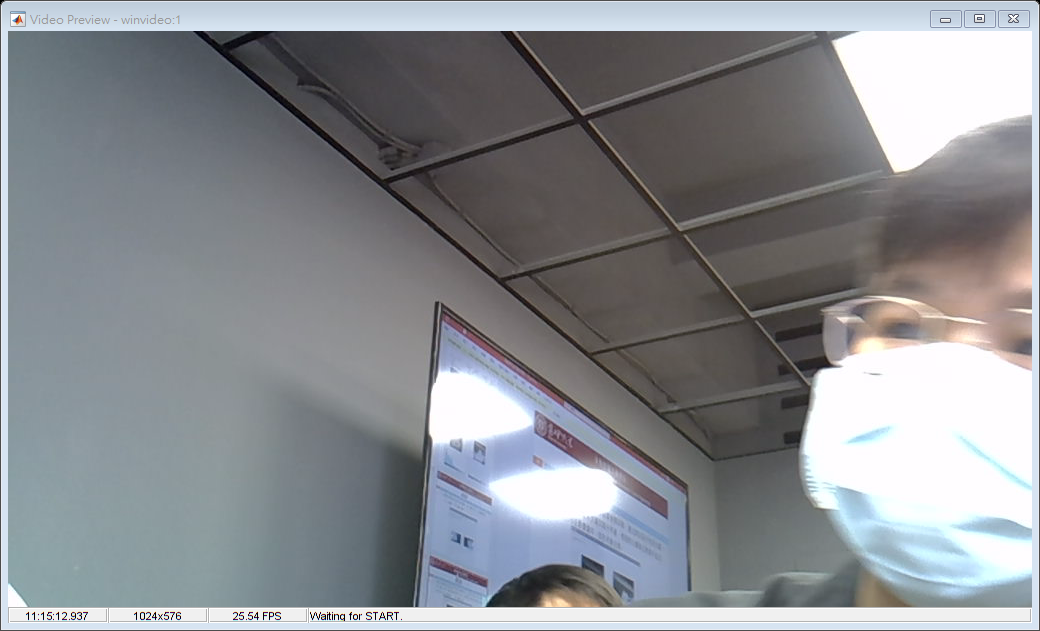

pause

photo = getsnapshot(vid);

[height,width,dim]=size(photo)

height = 576

width = 1024

dim = 3

for h=1:height
   for w=1:width
      r1(h,w)=photo(h,w,1);
   end
end

for h=1:height
   for w=1:width
      r2(h,w)=photo(h,w,2);
   end
end

for h=1:height
   for w=1:width
      r3(h,w)=photo(h,w,3);
   end
end

flr_r1=fliplr(r1);�
flr_r1=flipud(flr_r1)

flr_r1 = 576×1024 uint8 matrix
   165   166   163   170   185   192   195   205   198   173   153   141   140   141   151   161   178   173   185   192   172   136   119   111   128   132   143   139   127   110   116   129   128   133   141   147   153   154   156   155   168   195   204   195   200   203   203   208   213   216
   161   161   157   161   173   178   184   195   201   204   204   183   152   128   135   153   161   160   172   182   179   163   143   119   123   127   141   143   138   120   117   121   131   134   140   146   152   154   157   157   169   192   199   193   201   206   207   211   211   215
   159   160   154   156   164   168   173   186   200   209   220   213   187   156   144   145   151   153   160   165   172   177   165   134   120   121   135   144   147   132   121   114   131   133   139   144   152   155   159   159   171   188   197   194   202   208   210   212   209   215
   154   157   154   155   159   160   165   178   185   188   200


flr_r2=fliplr(r2);�
flr_r2=flipud(flr_r2)

flr_r2 = 576×1024 uint8 matrix
   208   209   207   214   229   236   239   249   241   216   189   177   172   173   180   190   210   205   218   225   202   166   143   135   142   146   149   145   127   110   112   125   120   125   132   138   142   143   142   141   151   178   183   174   178   181   179   184   190   193
   203   203   201   205   217   222   228   239   244   247   242   221   186   162   164   182   195   194   205   215   209   193   167   143   139   143   148   150   139   121   114   118   123   126   133   139   141   143   143   143   152   175   178   172   179   184   183   187   188   192
   199   200   196   198   206   210   217   230   242   251   255   251   223   192   177   178   185   187   193   198   204   209   191   160   137   138   143   152   150   135   119   112   126   128   132   137   141   144   145   145   154   171   176   173   180   186   186   188   186   192
   192   195   194   195   201   202   207   220   227   230   240


flr_r3=fliplr(r3);�
flr_r3=flipud(flr_r3)

flr_r3 = 576×1024 uint8 matrix
   231   232   227   234   247   254   255   255   255   232   207   195   192   193   201   211   230   225   232   239   209   173   150   142   149   153   148   144   110    93    84    97    98   103   108   114   115   116   112   111   116   143   145   136   137   140   136   141   139   142
   224   224   221   225   235   240   246   255   255   255   255   239   205   181   185   203   214   213   219   229   218   202   174   150   147   151   149   151   124   106    88    92   101   104   108   114   114   116   113   113   117   140   140   134   138   143   140   144   138   142
   218   219   215   217   225   229   235   248   255   255   255   255   241   210   195   196   204   206   207   212   212   217   199   168   146   147   145   154   138   123    97    90   103   105   107   112   114   117   115   115   119   136   138   135   139   145   143   145   136   142
   210   213   213   214   220   221   228   241   248   251   255

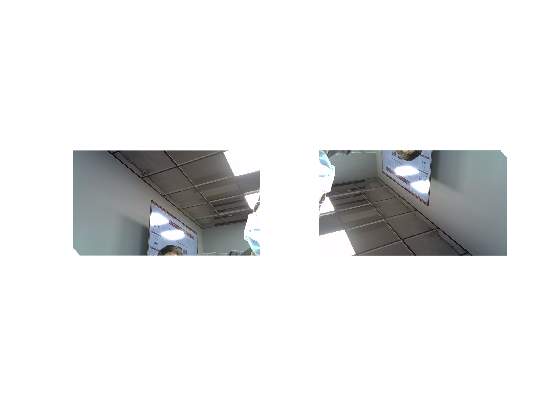


for h=1:height
   for w=1:width
      f(h,w,1)=flr_r1(h,w);
   end
end

for h=1:height
   for w=1:width
      f(h,w,2)=flr_r2(h,w);
   end
end

for h=1:height
   for w=1:width
      f(h,w,3)=flr_r3(h,w);
   end
end
subplot(1,2,1);imshow(photo)
subplot(1,2,2);imshow(f)